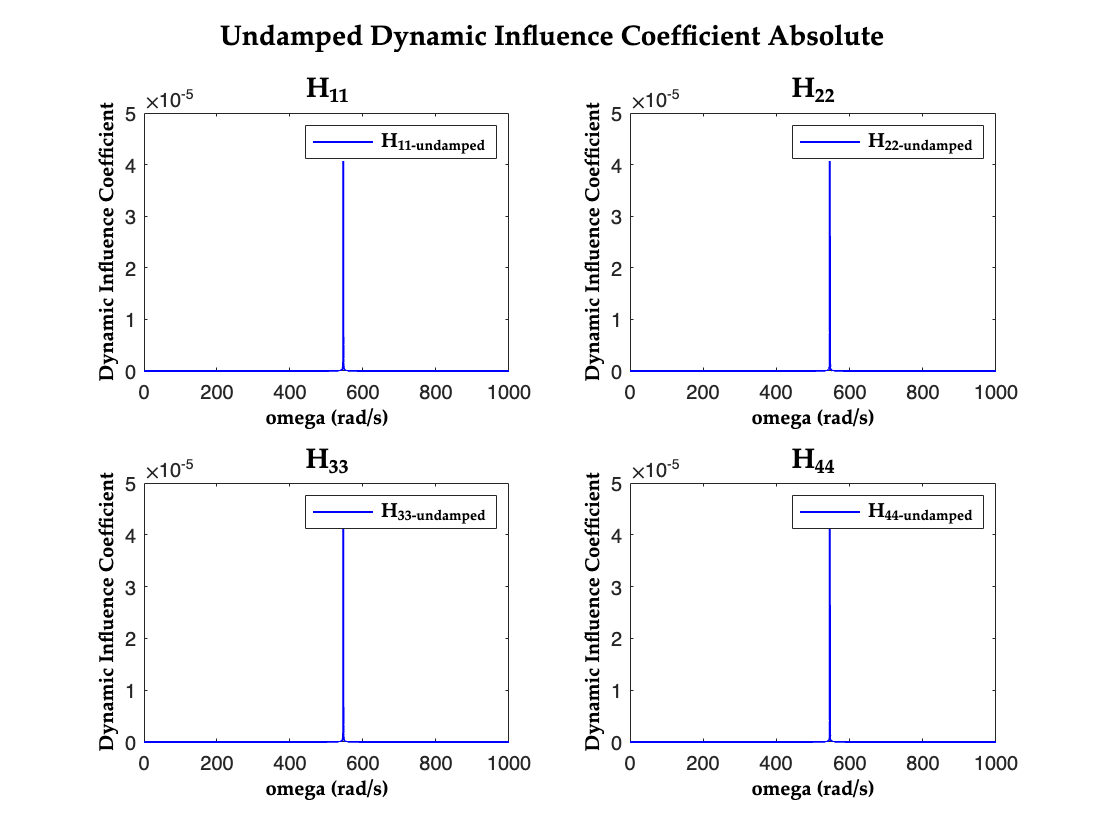

%%ASEN 5022 Dynamics of Aerospace Structures Project
%%Author: Chandan Varma Tamada
%%Dynamics of Coupled Blade System
clc; clear;

%%Blade Params
m_b = 6; %Mass of Blade (kg)
len = 1.5; %Length of Blade (m)
k_b = 300*(10^6); %Spring Constant of Blade (N/m)
n = 1; %Number of Blades

%%Rotor Params
m_r = 1000; %Mass of Rotor (kg)
k_r = 300*(10^6); %Spring Constant of Rotor (N/m)
c_r = 2000;

%%Time Params
t_end = 10; %Duration of Response
del_t = 0.1; %Time Interval
t = linspace(0,t_end,t_end/del_t); %Time Matrix

%%Blade Designation Params
i = 1:n;
theta = (2*(i-1)*pi)/n;

%%Coupled Rotor Blade Matrices
M = [m_r*eye(2),zeros(2,2*n);zeros(2*n,2),m_b*eye(2*n)];
K = [(n*k_b+k_r)*eye(2) [-k_b*ones(1,n) zeros(1,n);zeros(1,n) -k_b*ones(1,n)];[-k_b*ones(n,1) zeros(n,1);zeros(n,1) -k_b*ones(n,1)] k_b*eye(2*n)];
C = [zeros(2),zeros(2,2*n);zeros(2*n,2),zeros(2*n)];
C_damped = [c_r*eye(2),zeros(2,2*n);zeros(2*n,2),zeros(2*n)];

%Omega Params
omega_end = 1000; %Omega End Limit
del_omega = 0.1; %Omega Interval
omega = linspace(0,omega_end,omega_end/del_omega)'; %Omega Matrix

%%Calc Params
[V,E] = eig(K,M);

%%Dynamic Influence Coefficient Undamped Absolute
H_undamped_abs = zeros(length(omega),2+(2*n));
for k = 1:2+(2*n)
    H_undamped_abs(:,k) = abs((V(k,1)*V(k,1))./((E(1,1)-(omega.^2))*(V(:,1)'*M*V(:,1))))+abs((V(k,2)*V(k,2))./((E(2,2)-(omega.^2))*(V(:,2)'*M*V(:,2))))+abs((V(k,3)*V(k,3))./((E(3,3)-(omega.^2))*(V(:,3)'*M*V(:,3))))+abs((V(k,4)*V(k,4))./((E(4,4)-(omega.^2))*(V(:,4)'*M*V(:,4))));
end

%%Plot
figure;
sgtitle('Undamped Dynamic Influence Coefficient Absolute','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,1);
plot(omega,H_undamped_abs(:,1),'b',LineWidth=1);
legend('H_{11-undamped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{11}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,2);
plot(omega,H_undamped_abs(:,2),'b',LineWidth=1);
legend('H_{22-undamped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{22}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,3);
plot(omega,H_undamped_abs(:,3),'b',LineWidth=1);
legend('H_{33-undamped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{33}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,4);
plot(omega,H_undamped_abs(:,4),'b',LineWidth=1);
legend('H_{44-undamped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{44}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');

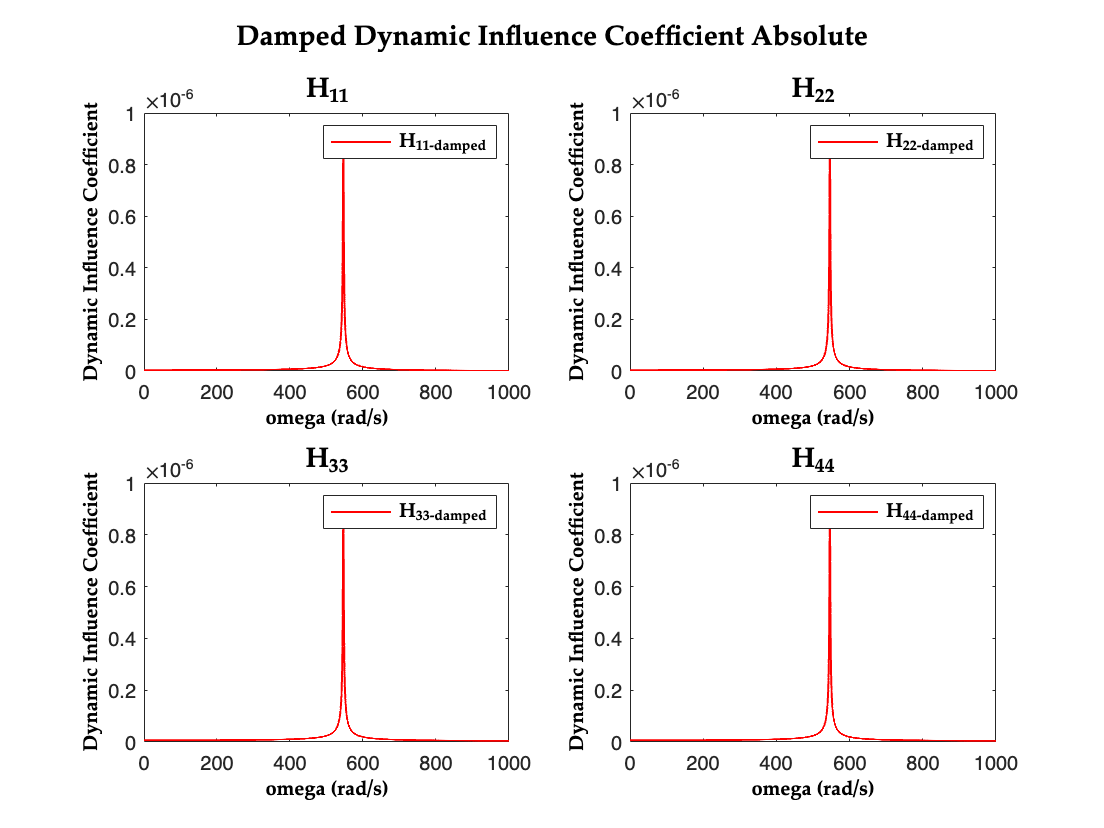

%exportgraphics(gcf,'sol_4_undamped_dynamic_coeff_abs.jpg','Resolution',300);

%%Dynamic Influence Coefficient damped - Absolute
H_damped_abs = zeros(length(omega),2+(2*n));
for k = 1:2+(2*n)
    H_damped_abs(:,k) = abs((((V(k,1)*V(k,1))/(V(:,1)'*M*V(:,1)))*(1./((E(1,1))-(omega.^2)+(((V(:,1)'*C_damped*V(:,1))*omega*1i)/(V(:,1)'*M*V(:,1)))))))+abs((((V(k,2)*V(k,2))/(V(:,2)'*M*V(:,2)))*(1./((E(2,2))-(omega.^2)+(((V(:,2)'*C_damped*V(:,2))*omega*1i)/(V(:,2)'*M*V(:,2)))))))+abs((((V(k,3)*V(k,3))/(V(:,3)'*M*V(:,3)))*(1./((E(3,3))-(omega.^2)+(((V(:,3)'*C_damped*V(:,3))*omega*1i)/(V(:,3)'*M*V(:,3)))))))+abs((((V(k,4)*V(k,4))/(V(:,4)'*M*V(:,4)))*(1./((E(4,4))-(omega.^2)+(((V(:,4)'*C_damped*V(:,4))*omega*1i)/(V(:,4)'*M*V(:,4)))))));
end

%%Plot
figure;
sgtitle('Damped Dynamic Influence Coefficient Absolute','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,1);
plot(omega,H_damped_abs(:,1),'r',LineWidth=1);
legend('H_{11-damped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{11}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,2);
plot(omega,H_damped_abs(:,2),'r',LineWidth=1);
legend('H_{22-damped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{22}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,3);
plot(omega,H_damped_abs(:,3),'r',LineWidth=1);
legend('H_{33-damped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{33}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,4);
plot(omega,H_damped_abs(:,4),'r',LineWidth=1);
legend('H_{44-damped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{44}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');

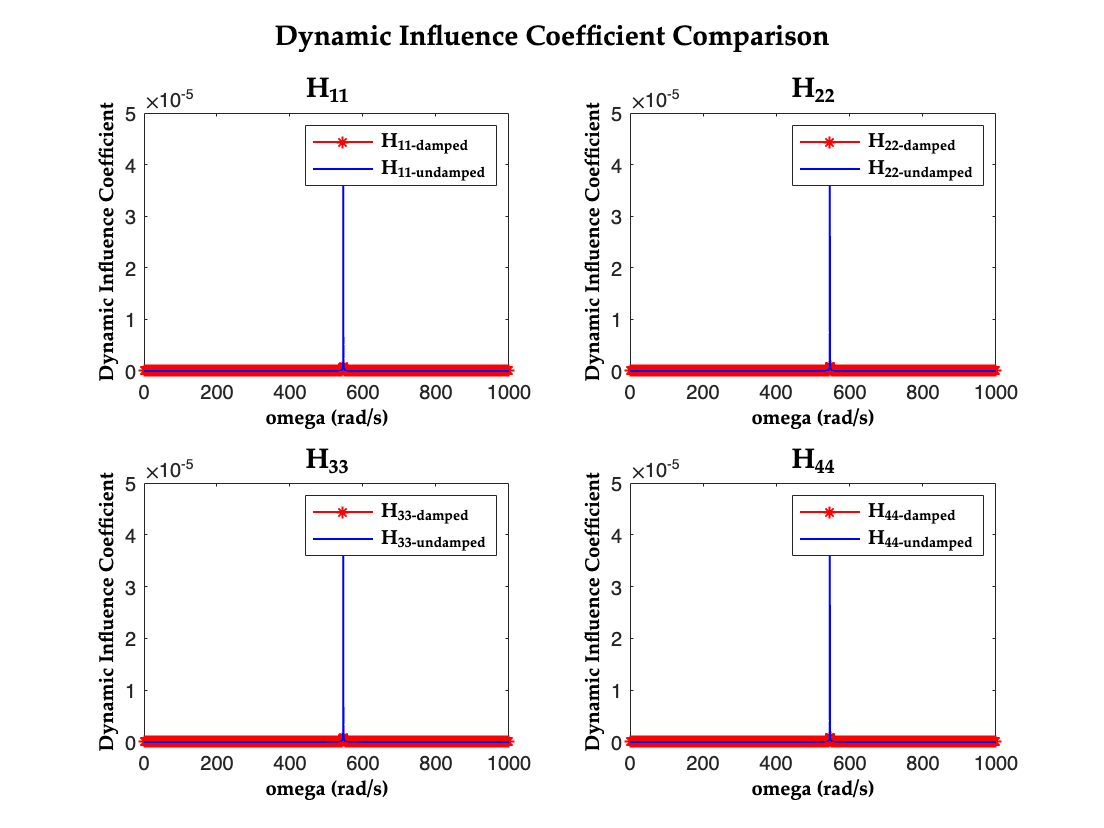

%exportgraphics(gcf,'sol_4_damped_dynamic_coeff_abs.jpg','Resolution',300);

%%Plot
figure;
sgtitle('Dynamic Influence Coefficient Comparison','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,1);
plot(omega,H_damped_abs(:,1),'-*r',omega,H_undamped_abs(:,1),'b',LineWidth=1);
legend('H_{11-damped}','H_{11-undamped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{11}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,2);
plot(omega,H_damped_abs(:,2),'-*r',omega,H_undamped_abs(:,2),'b',LineWidth=1);
legend('H_{22-damped}','H_{22-undamped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{22}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,3);
plot(omega,H_damped_abs(:,3),'-*r',omega,H_undamped_abs(:,3),'b',LineWidth=1);
legend('H_{33-damped}','H_{33-undamped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{33}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(2,2,4);
plot(omega,H_damped_abs(:,4),'-*r',omega,H_undamped_abs(:,4),'b',LineWidth=1);
legend('H_{44-damped}','H_{44-undamped}','FontSize',10,'FontWeight','bold','FontName','Palatino');
xlabel('omega (rad/s)','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Dynamic Influence Coefficient','FontSize',10,'FontWeight','bold','Color','k','FontName','Palatino');
subtitle('H_{44}','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');

%exportgraphics(gcf,'sol_4_damped_dynamic_coeff_comp.jpg','Resolution',300);